# Lab 6 - Confidence Intervals

Thomas Conaway

Lab Partners: Jeff Jiang, Avi Soval

Time: 12 hours

We will be exploring injections of simulated signals into signal free background data.

Generating a fake LHC background with mean 100:

clc; clear; close all;
lhcbg = makedist("Poisson","lambda",100);

## Problem 1

Determining the 5 sigma sensitivity threshold for our fake LHC background.

fivesigma = icdf(lhcbg,1 - 3E-7)

fivesigma = 154

## Problem 2

We will inject a set of moderately strong single strength signals into the background. To be moderately strong we will pick a signal strength within the range 8 to 30 sigma.

abs(norminv(cdf(lhcbg,300,'upper')))

ans = 16.1463

A signal strength of 300 is within this range, so we will use this as the strength and proceed:

size = 10000;
poissnoise = poissrnd(100,[1,size]);
signal300 = zeros(1,size);
signal300(randi(numel(signal300),[1,500])) = 300; % sets 500 random elements to 300
obssignal = poissnoise + signal300;

**a)** Histogramming how bright the observed signal appears to be:

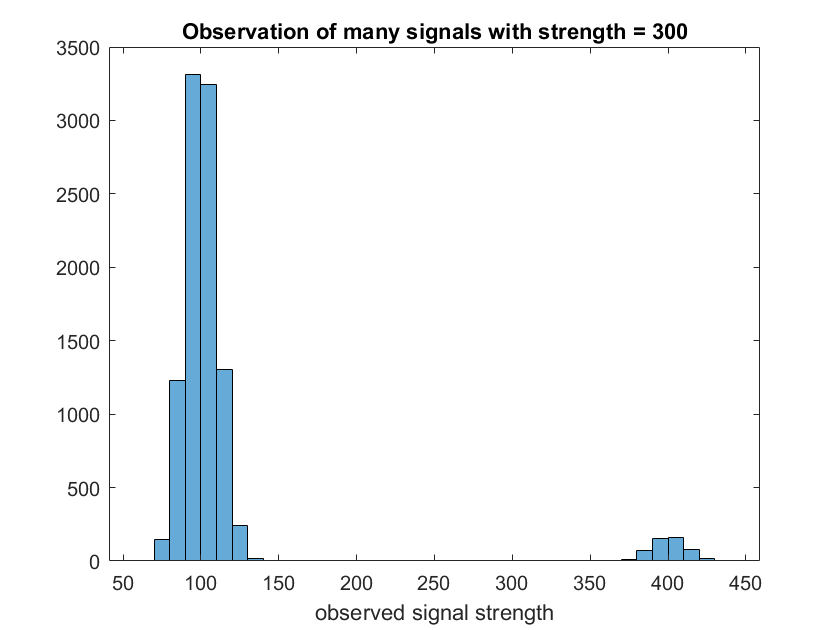

histogram(obssignal);
title("Observation of many signals with strength = 300");
xlabel("observed signal strength");

Signal appears as the group of bins centered at 400. Shape appears to be the same as the background noise. This histogram is telling us that the observed signal can take on a range of values that it picks up from the background.

**b)** Observed signal appears biased because it is not distributed on the true injected signal of 300; it is stronger by 100. The observed signal remains symmetric like the background, but is centered at 400.

## Problem 3

Now we will make a suite of injected signals, ranging from 0 to well above 5 sigma:

abs(norminv(cdf(lhcbg,550,'upper')))

ans = 31.2675

signals = 0:1:550; % 550 gets a little over 31 sigma

a) We will now examine observed signals for a range of injected signals, plotted as a 2d histogram of injected vs. observed signals. Horizontal row slices of this 2d histogram form fixed injected signal 1d histograms and vertical slices form the 1d histograms of fixed observation signals.

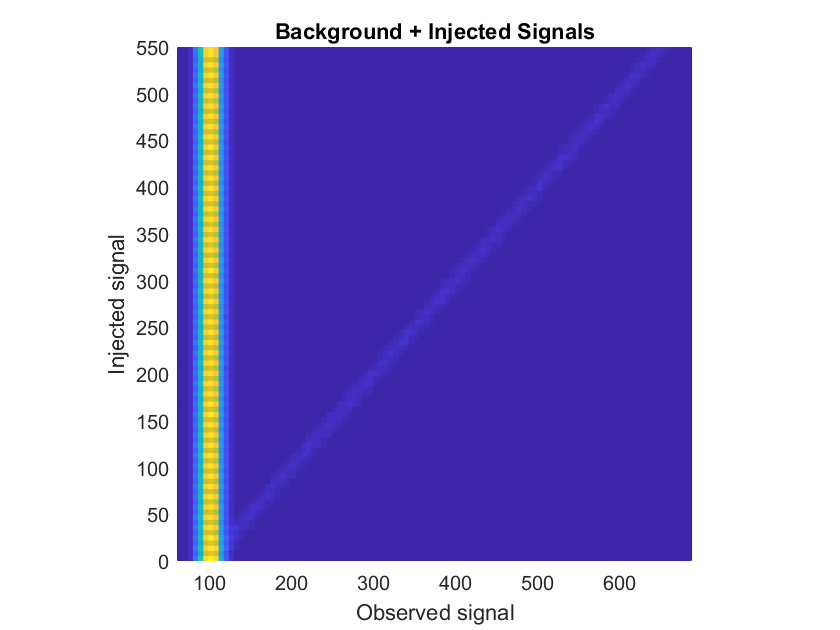

size = 10000;
poissnoise = poissrnd(100,[1,size]); %
poisssignalsyval = zeros(numel(signals),size);
obssignals = zeros(numel(signals),size);
justsignals = zeros(numel(signals),size);
for k = 1:numel(signals) % loop to build and stack each row slice
    poisssignalsyval(k,:) = signals(k);
    signalk = zeros(1,size);
    indices = randi(numel(signalk),[1,500]);
    signalk(indices) = signals(k);    
    obssignals(k,:) = poissnoise + signalk;
    justsignals(k,indices) = obssignals(k,indices);
end
justsignals(justsignals == 0) = nan; % so it plays nice with histogram2

histogram2(obssignals,poisssignalsyval,100,'DisplayStyle','tile','ShowEmptyBins','on');
title("Background + Injected Signals");
axis square;
ylabel("Injected signal");
xlabel("Observed signal");

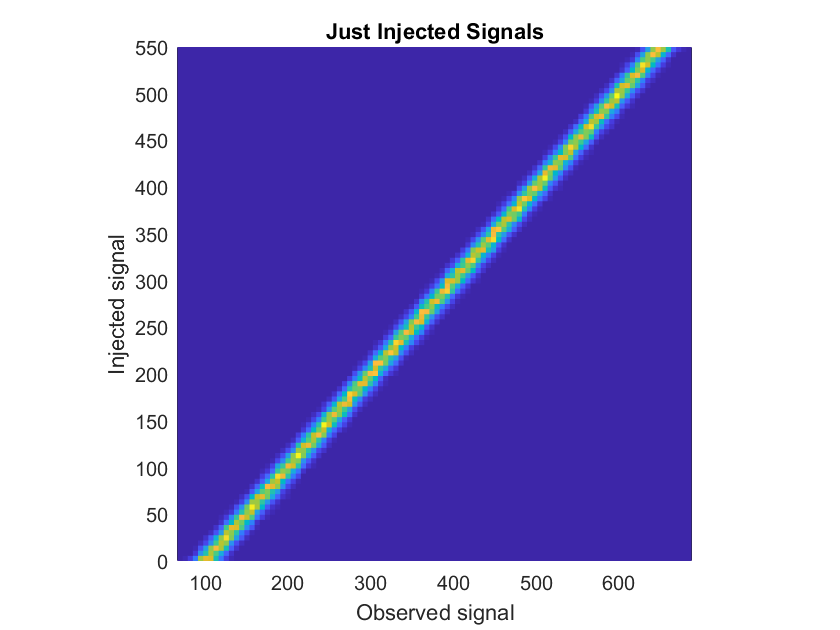

histogram2(justsignals,poisssignalsyval,100,'DisplayStyle','tile','ShowEmptyBins','on');
title("Just Injected Signals");
axis square;
ylabel("Injected signal");
xlabel("Observed signal");

**b)** We should check that we get the same answer as in Problem 2 with the same injected signal:

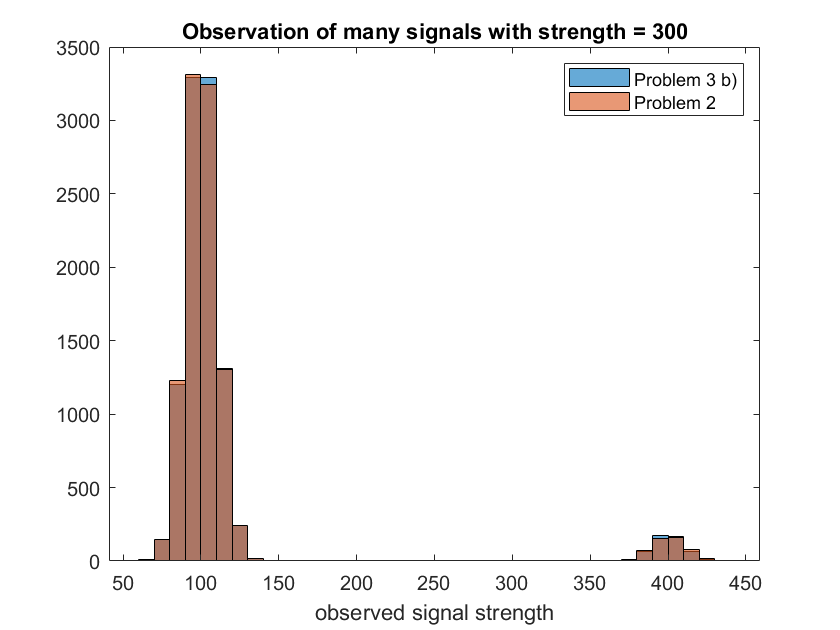

histogram(obssignals(300,:));
hold on;
histogram(obssignal);
title("Observation of many signals with strength = 300");
xlabel("observed signal strength");
legend("Problem 3 b)","Problem 2");
hold off;

Looks good. The method I used for generating the suite produced a different random set of noise, but they still closely follow the original histogram for an injected signal of 300. 

**c)** We will select an observed signal of 300 (much higher than 5 sigma) and examine its vertical slice histogram:

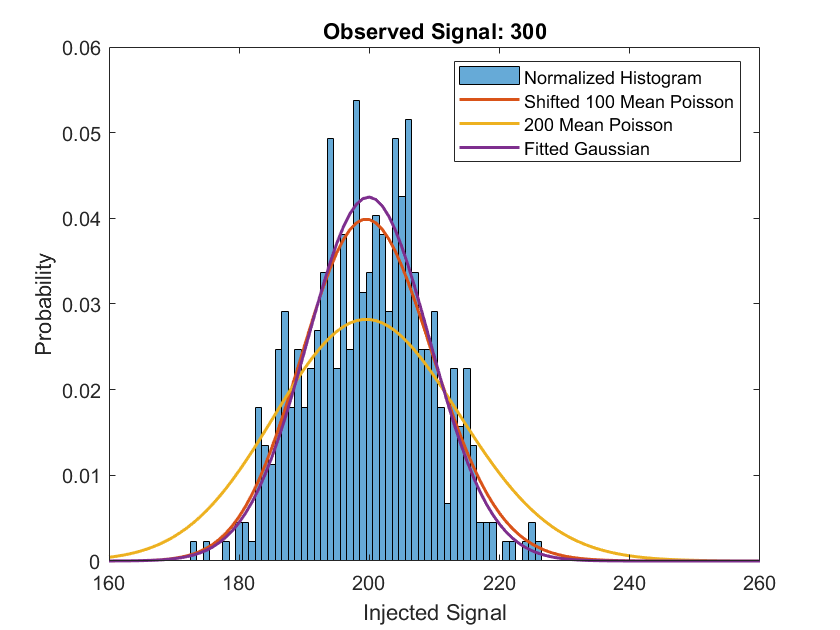

injected = poisssignalsyval(abs(justsignals - 300)<0.05);
binedges = min(injected)-0.5:max(injected)+0.5;
histogram(injected,binedges,'Normalization','pdf');
title("Observed Signal: 300");
xlabel("Injected Signal");
ylabel("Probability");
x = 60:160;
y = pdf("Poisson",x,100);
hold on;
plot(x+100,y,"LineWidth",1.5);
x2 = 160:260;
y2 = pdf("Poisson",x2,200);
plot(x2,y2,"LineWidth",1.5);
fitted = fitdist(injected,"Normal");
y3 = pdf(fitted,x2);
plot(x2,y3,"LineWidth",1.5);
legend("Normalized Histogram","Shifted 100 Mean Poisson","200 Mean Poisson","Fitted Gaussian","location","best");
hold off;

This histogram gives the probabilities for the injected signals that can produce an observed signal of 300. It also shows the range of signal values likely to produce the observed signal. Shape suggests it could either be Gaussian or that it may still be following the 100 Poisson noise of the background, so I've overlaid these curves on the histogram. It's a rough fit in either case, but it does still appear to be in alignment with the histogram. This is clearly not a 100 mean Poisson (which wouldn't be centered on the distribution) so the Gaussian may be the more appropriate fit. Poisson distributions appear Gaussian for larger means, which explains the similarity in shape between these two candidate curves. This is NOT a 200 mean Poisson, which would appear much more spread out.

**d)** For an observed signal of 300, the 1 sigma uncertainty on the true signal strength of 200 are the bounds around the true signal that contain 68% of the data.

% finding 1 sigma for this distribution slice and calculating uncertainty values.
% 1 sigma contains 68% of the distribution, so 34% below and
% above the mean (true value) is what we want to integrate to.
[p, edges] = histcounts(injected,binedges,'Normalization','pdf');
sumup = 0;
lowerunc = 0;
meanval = 0;
upperunc = 0;
for k = 1:numel(p)
    sumup = sumup + p(k);
    if sumup > 0.84 && upperunc == 0
        upperunc = edges(k) + 0.5;
        break
    end
    if sumup > .50 && meanval == 0
        meanval = edges(k) + 0.5;
    end
    if sumup > 0.16 && lowerunc == 0
        lowerunc = edges(k) + 0.5;
    end
end
disp("Upper threshold is: " + upperunc);

Upper threshold is: 209


disp("Lower threshold is: " + lowerunc);

Lower threshold is: 190


disp("1 Sigma Uncertainty: " + meanval + " [+" + (upperunc-meanval) + "|-" + (meanval-lowerunc) + "]");

1 Sigma Uncertainty: 200 [+9|-10]


% fitted distribution produces similar values, but must be rounded
icdf(fitted,[0.16,0.50,0.84])

ans =   190.5502  199.8879  209.2256


**e)** It is not perfectly symmetric because of the different uncertainty bounds, but it is close enough that I will say it is (roughly) symmetric. This may be due to the random noise or to the method I used to find thresholds using a "blocky" histogram which makes getting to the exact threshold tricky. It is not biased because the injected signals nearly matches the true injected one with roughly equal uncertainty for being above or below it. This makes sense because we expect the true injected signal to be the one most likely to produce our observation and that neighboring injected signals (same distance above and below) are as likely as eachother (but less frequently than the true injected signal) to produce the observation owing to the symmetry of the background they pick up.

## Problem 4

We will now look at what happens when we have a weak signal (within 1 sigma of the background).

abs(norminv(cdf(lhcbg,105,'upper')))

ans = 0.5616

**a)** We will look at an observed signal of 105 and calculate the injected signal pdf() histogram as we did above.

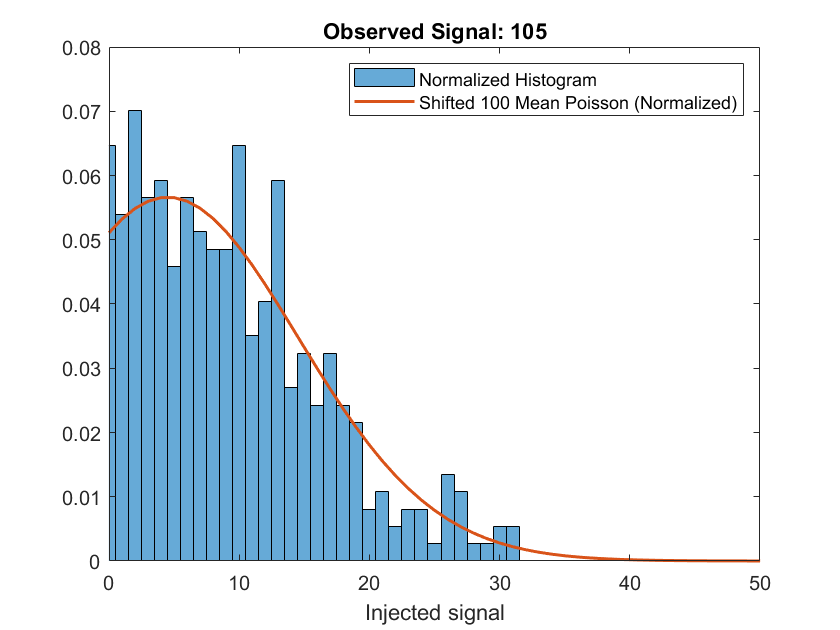

weaksignal = 105;
injected3 = poisssignalsyval(abs(justsignals - weaksignal)<0.05);
binedges3 = min(injected3)-0.5:max(injected3)+0.5;
histogram(injected3,binedges3,'Normalization','pdf');
title("Observed Signal: " + weaksignal);
xlabel("Injected signal");
xt = 95:150;
pdist = makedist("Poisson","lambda",100);
yt = pdf(pdist,xt);
yt = yt/sum(yt); % normalized pdf
hold on;
plot(xt - 95,yt,"LineWidth",1.5);
legend("Normalized Histogram","Shifted 100 Mean Poisson (Normalized)");
xlim([0,50]);
hold off;

Resulting pdf() extends to zero.

**b)** If the true signal pdf() extends to zero then it becomes probable for the background (no signal) to produce the observation. There are also no injected signals below zero to be counted so the histogram is no longer roughly symmetrical.

**c)** Even if the observed signal is too weak to claim a detection, we can determine an upper confidence bound value which the true signal would have to be less than, 95% of the time.

binedges3 = min(injected3)-0.5:max(injected3)+0.5;
p3 = histcounts(injected3,binedges3,'Normalization','pdf');
sumup3 = 0;
for k = 1:numel(p3)
    sumup3 = sumup3 + p3(k);
    if sumup3 > 0.95
        break;
    end
end
disp("95% confidence upper bound (integrating histogram by hand): " + (binedges3(k) + 0.5));

95% confidence upper bound (integrating histogram by hand): 24


probt = (1 - cdf(pdist,95)) * 0.05;
disp("95% confidence upper bound (integrating pdf with icdf): " + (icdf(pdist,1 - probt) - 95));

95% confidence upper bound (integrating pdf with icdf): 24
